# Introduction to Simple Linear Regression

Read data from an external file (SalaryData.csv),  The fiirst column represents years in service while the second column represents annual salary. The data set can also be obtained from [https://www.kaggle.com/karthickveerakumar/salary-data-simple-linear-regression](https://www.kaggle.com/karthickveerakumar/salary-data-simple-linear-regression).

data=readtable('SalaryData.csv','ReadVariableNames',false);
data.Properties.VariableNames = {'YearsExperience','Salary'}

data = 30×2 table
    YearsExperience    Salary
    _______________    ______

          1.1          39343 
          1.3          46205 
          1.5          37731 
            2          43525 
          2.2          39891 
          2.9          56642 
            3          60150 
          3.2          54445 
          3.2          64445 
          3.7          57189 
          3.9          63218 
            4          55794 
            4          56957 
          4.1          57081 
          4.5          61111 
          4.9          67938 


Build the regression model.

mdl=fitlm(data.YearsExperience,data.Salary)

mdl = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate      SE      tStat       pValue  
                   ________    ______    ______    __________

    (Intercept)     25792      2273.1    11.347     5.512e-12
    x1               9450      378.75     24.95    1.1431e-20


Number of observations: 30, Error degrees of freedom: 28
Root Mean Squared Error: 5.79e+03
R-squared: 0.957,  Adjusted R-Squared: 0.955
F-statistic vs. constant model: 623, p-value = 1.14e-20

Get predictions from the model and plot with data

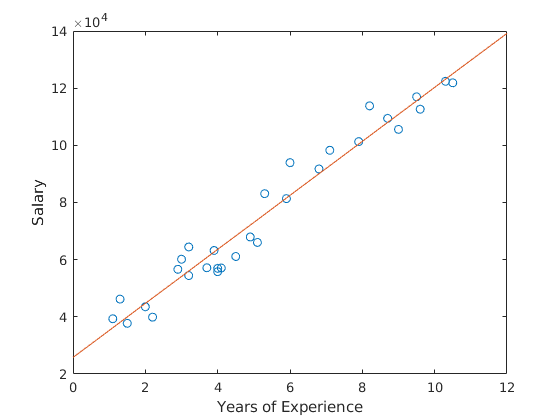

x=linspace(0,12,100)';
ypred=predict(mdl,x);
plot(data.YearsExperience,data.Salary,'o',x,ypred)
xlabel('Years of Experience')
ylabel('Salary')